

clc
clear
s=tf('s');
Gs=(s+4)/((s+2)*(s-1))

Gs =
 
     s + 4
  -----------
  s^2 + s - 2
 
Continuous-time transfer function.



ProcentajeCriterioTs=0.02;
CriterioRiso=[0.10 0.90];
ParametroSys(Gs,ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  1.00e+00    -1.00e+00       1.00e+00        -1.00e+00    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    


Resultados =     '
     Ts(2.00)=NaN
     Tr=NaN
     Mp=NaN
     Tp=Inf
     Tao=NaN
     ValorF=-2.0000
     '


ans = NaN

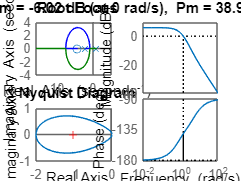

figure(1)
step(Gs)
figure(2)
subplot(221),rlocus(Gs)
subplot(223),nyquist(Gs)
subplot(122),margin(Gs)

%sisotool(Gs)
%% Calcular polos deseados y posicion
clc
Mp=0.15; Ts=1

Ts = 4.5000

Zeta=-log(Mp)/(sqrt(pi^2+log(Mp)^2))

Zeta = 0.5912

%tomo un zeta mayor por critierios del diseñador para tener menor sobrepico
%Zeta=0.8
Sigma=4/Ts

Sigma = 0.8889

rlocus(Gs)
sgrid(Zeta,0)
Wn=4/(Zeta*Ts)

Wn = 1.5036

Wd=Wn*sqrt(1-Zeta^2)

Wd = 1.2128

[Phi,Theta,Alpha,P,Z,Kc,C]=CompensadorBisectriz_SigmaWdZeta(Gs,Sigma,Wd,Zeta,0)

Phi = 353.5052

Theta = 36.2390

Alpha = 63.1195

P = 1.4196

Z = 1.5927

Kc = 1.0439

C =
 
  1.044 s + 1.663
  ---------------
     s + 1.42
 
Continuous-time transfer function.



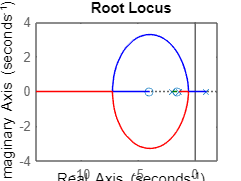


%% 
clc
close all
%C=51.699*(s+3.892)/(s+16.12)
GsC=C*Gs;
rlocus(GsC)

Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.89e-01 + 1.21e+00i     5.91e-01       1.50e+00         1.12e+00    
 -8.89e-01 - 1.21e+00i     5.91e-01       1.50e+00         1.12e+00    
 -1.69e+00                 1.00e+00       1.69e+00         5.93e-01    


Resultados =     '
     Ts(2.00)=3.6429
     Tr=1.0732
     Mp=11.7594
     Tp=2.2278
     Tao=0.7919
     ValorF=1.7449
     '


ans = 3.6429

ErroEpEvEa(GsC)

ans = -0.7449

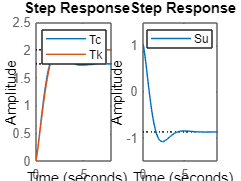

subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend